#  Battery Cell Thermal Modeling

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Battery thermal modeling is an important part of a battery design pack design. Charging and discharging of a battery generates heat that could decrease the battery performance and potentially make its usage dangerous. In this script, you will learn to identify the source of the heat and how to model it.

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline** using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Why does the battery heat up?

Before starting this script, it is encouraged to learn more about battery modeling by following the[ BatteryModeling.mlx](matlab:open('..\FunctionLibrary\BatteryModeling.mlx')) script series. You will learn to model the battery cell in this script using an equivalent circuit model. Eventually, you will end up with a dynamic equivalent circuit model using fundamental electronic components (resistor and capacitor) to model the behavior of the battery cell:

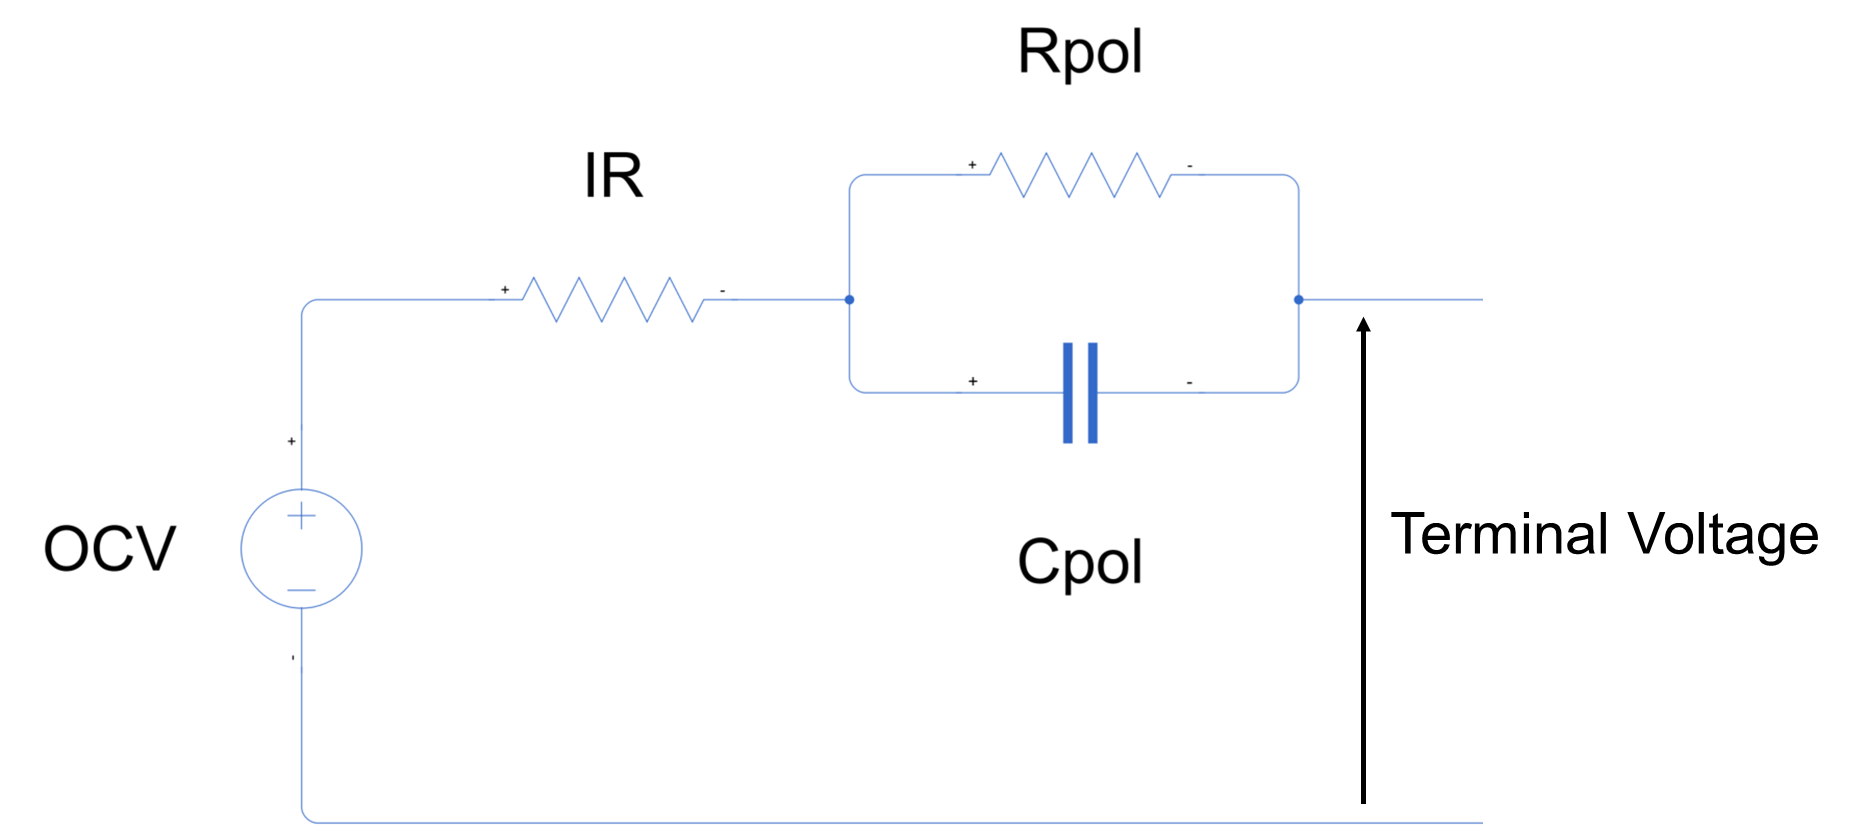

In the equivalent circuit model above, the resistor IR represents the internal resistance, and Rpol and Cpol represent the polarization resistor and capacitor, respectively.

 **Exercise. **What 

CheckExercise1("R")
 

In the rest of the script, we will work on modeling the heat generated by the resistor in the equivalent circuit model.

## Fundamentals of Thermal Modeling

### Heat Generation in Battery Cells

Heat generation within a battery cell can stem from two primary sources: Joule heating and chemical reactions. 

- **Joule heating:** occurs when the flow of current through the battery resistance generates heat. 

- **Chemical reactions** within the battery can also produce heat due to the internal processes involved in charging and discharging. 

However, in cases where the focus is not on modeling the chemical reactions, attention is directed solely towards the heat generated by Joule heating. This approach simplifies the analysis by concentrating on the thermal effects directly linked to electrical resistance and current flow within the battery, excluding the complexities introduced by chemical thermodynamics.

### Mathematical Modeling

To model the temperature of a battery with a uniform temperature assumption, we can use a simplified form of the energy conservation equation. Let's denote $T$ as the uniform temperature of the battery cell, $Q_{gen}$ as the rate of heat generation due to Joule heating, $Q_{loss}$ as the rate of heat loss to the surroundings, and $m$ as the mass of the battery cell. Let $c_p$ represent the specific heat capacity of the battery material. The conservation of energy, considering only Joule heating and uniform temperature within the cell, can be expressed as:


$$\frac{d}{dt}(M_{Th} T) = Q_{gen} - Q_{loss} \qquad (1)$$


Where:

- $\frac{d}{dt}(M_{Th} T)$ Represents the rate of change of internal energy within the battery.

- $Q_{gen}$ Is the heat generated by the charge/discharge

- $Q_{loss}$ Is the potential heat loss, for example, through a cooling system

Assuming the cell temperature is uniform simplifies the spatial distribution of temperature, allowing the model to focus on the temporal temperature changes $(T)$ over time $(t)$. This equation forms the basis for predicting the battery's thermal behavior under various operating conditions.

  **Try.** Load the battery properties

 
load(fullfile("Data","LiIonCell.mat"))
LiIon
Datasheet = LiIon.Characteristic

## Simulate Battery Cell Temperature

To simulate the 

We are going to approximate the solution by using discrete math to update the temperature:


$$T^{k+1} = T^k + \frac{T_s}{M_{Th}}\left(Q_\text{gen}-Q_\text{loss}\right)$$


We will consider that the battery is fully-insulated, so that $Q_\text{loss} = 0$.

  **Try.** Define all the problem parameters

SampleTime = 1; % [s]
InitialTemperature = 20; % [C]
ThermalMass = LiIon.ThermalMass; % [J/K]
DischargeCurrent = 1; % [A]
InternalResistance = mean(Datasheet.R0); % [Ohm]

In the previous equation, we define two source terms: one for the heat generated by the battery and one for loss by the battery through cooling.

 **Exercise.** How would you model the heat generated by Joule heating?

- 
$$Q_{gen}=Vt$$


- 
$$Q_{gen}=R_0i^2$$


- 
$$Q_{gen}=Vi$$


- 
$$Q_{gen}=i^2t$$


With $V$ the battery cell terminal voltage, $R_0$ the internal resistance, $i$ the current, and $t$ the time.

CheckJouleHeating("2")

 **Exercise. **Complete the following code to update the temperature using the previous exercise and the equation above.

function T_kp1 = UpdateWithoutCooling(T_k,Ts,M,R0,i)

    % Complete the body of the function below to represent the the
    % temperature update from equation 2:
    T_kp1 = T_k ;

You are right, resistor are known to generate heat when current is applied to them.



end

CheckUpdateWithoutCooling(@(T,ts,M,R0,i) UpdateWithoutCooling(T,ts,M,R0,i))
 

We can now simulate the evolution of the battery cell temperature during charge/discharge.

  **Try.** Select your parameters and run the simulation.

TotalTime = 3600; %(s) Total simulation time
Ts = 0.1; %(s) Sample time
T0 = 20; %(degC) Initial temperature
 


Time = 0:Ts:TotalTime;
Temperature = zeros(size(Time));
Temperature(1) = T0;
for k = 2:length(Time)
    Temperature(k) = UpdateWithoutCooling(Temperature(k-1),SampleTime,ThermalMass,InternalResistance,DischargeCurrent);
end


LiIon = struct with fields:
    Characteristic: [101×16 table]
            Height: 65.1000
          Diameter: 18.2400
            Weight: 46.5000
          Capacity: 2.8000
             Shape: "Cylindrical"
       ThermalMass: 43.2000
              Rpol: 0.0200
              Cpol: 10

figure

Datasheet = 101×16 table
    SoC      OCV        R0       OCV_20b    OCV_10b    OCV_0     OCV_25    OCV_40    OCV_60    R0_20b     R0_10b      R0_0       R0_25      R0_40      R0_60      dOCV 
    ____    ______    _______    _______    _______    ______    ______    ______    ______    _______    _______    _______    _______    _______    _______    ______
       0    2.5496    0.14748    2.5496     2.5496     2.5496    2.5496    2.5496    2.5496    

plot(Time,Temperature)
title("Battery Cell Heating without Cooling")
xlabel("Time [s]")
ylabel("Temperature [C]")

 **Reflect.** What would happen to the battery temperature if the current was high (> 5 A)?

### Modeling cooling

In the previous section, the battery did not have any cooling.

  **Try.** What kind of system would you use to cool down the battery?

Choice = "NatConv";
CheckCoolingSystem(Choice)
 

 **Exercise.** Complete the function below to compute the heat loss of the battery based on the cooling system you preferred in the previous interaction.

function Qloss = ComputeHeatLoss(Temperature)
    
    % Modify the body of the function to match the type of cooling you
    % picked above:
    h = 1;
    Surface = 1;
    T_ambient = 1;
    Eff = 1;
    
    Qloss = 0;
    
end


Good job! You selected the right answer.


 
CheckComputeHeatLoss(Choice,@(T) ComputeHeatLoss(T))

The function to update the temperature with cooling is a simple modification of the one defined previously without cooling:

function T_kp1 = UpdateWithCooling(T_k,Ts,M,R0,i)

    % Modify the body of the function below to add
    T_kp1 = T_k + Ts/M*(R0*i^2 - ComputeHeatLoss(T_k));

end

  **Try.** Set your simulation parameters and run the simulation with (and without) cooling.

TotalTime = 3600; %(s) Total simulation time
Ts = 0.1; %(s) Sample time
Time = 0:Ts:TotalTime;

Good job! You defined the temperature update correctly.


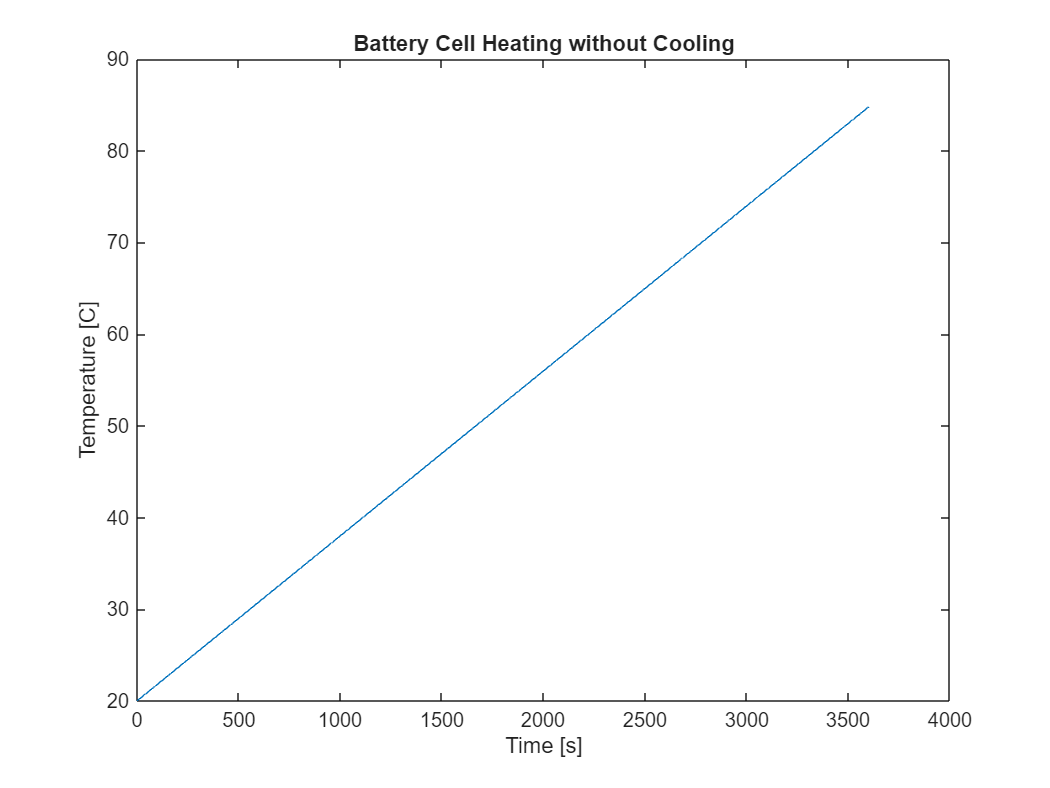

T0 = 20; %(degC) Initial temperature
 

% Simulate with cooling
Temperature = zeros(size(Time));
Temperature(1) = T0;
for k = 2:length(Time)
    Temperature(k) = UpdateWithCooling(Temperature(k-1),SampleTime,ThermalMass,InternalResistance,DischargeCurrent);
    % TemperatureWithoutCooling(k) = UpdateWithoutCooling(TemperatureWithoutCooling(k-1),SampleTime,ThermalMass,InternalResistance,DischargeCurrent);
end
figure
plot(Time,Temperature)
title("Battery Cell Heating")
xlabel("Time [s]")
ylabel("Temperature [C]")


% Simulate without cooling
Temperature = zeros(size(Time));
Temperature(1) = T0;
for k = 2:length(Time)
    Temperature(k) = UpdateWithoutCooling(Temperature(k-1),SampleTime,ThermalMass,InternalResistance,DischargeCurrent);

end
hold on
plot(Time,Temperature)
hold off
legend("With cooling","Without cooling")

  **Try.** All of the cooling mechanisms offered at the beginning of this section were valid ways to cool down the battery cell; you should try implementing different cooling by restarting this section from here.

## Further exploration

In this script, we modeled the temperature of a single battery cell with constant internal resistance. In reality, the internal resistance and the open circuit voltage of a battery 

  **Try.** Plot the Internal Resistance as a function of the State of Charge at different temperatures.

figure
plot(Datasheet.SoC,Datasheet.R0_20b,DisplayName = "-20 $^\circ C$")
hold on
plot(Datasheet.SoC,Datasheet.R0_10b,DisplayName = "-10 $^\circ C$")

Yes, you could use natural convection with the following formula:


$$Q_{\mathrm{loss}}=h\,S\,\left(T-T_{\mathrm{ambient}}\right)$$

with:
  - h the natural convection heat transfer coefficient
  - S the outer surface of the battery cell
  - T the battery temperature
  - T ambient the ambient temperature
For natural convection you can use:
  h = 1 W/(m2*K)
  T_ambient = 20 C
  S = 0.004 m^2


plot(Datasheet.SoC,Datasheet.R0_0,DisplayName = "0 $^\circ C$")
plot(Datasheet.SoC,Datasheet.R0_25,DisplayName = "25 $^\circ C$")
plot(Datasheet.SoC,Datasheet.R0_40,DisplayName = "40 $^\circ C$")
plot(Datasheet.SoC,Datasheet.R0_60,DisplayName = "60 $^\circ C$")
hold off
legend(Interpreter="latex",Location="best")
ylabel("$R_0\quad(\Omega)$",Interpreter="latex")
xlabel("SoC (-)",Interpreter="latex")

## Conclusion

By integrating thermal models with Model-Based Design tools, engineers can simulate various operating conditions and design strategies to ensure the battery system performs safely and efficiently under all circumstances. This approach reduces the need for extensive physical testing and accelerates the development process of battery systems.

In this script, we modeled the thermal behavior of a single battery cell. In large battery packs, such as the one used in electric vehicles, the battery pack can comprise up to 10,000 cells. In this situation, manually deriving the heat equation for each battery cell would be complex, especially considering the heat transfer happening from one cell to another. Simscape Battery includes thermal modeling for large battery packs and offers the possibility of pairing the battery domain with a thermal model for advanced heat transfer modeling. Learn more about this capacity in the [Build Model of Battery Module with Thermal Effects](https://uk.mathworks.com/help/simscape-battery/ug/build-battery-module-thermal-effects.html) documentation example. 

## Helper Functions

function CheckExercise1(Ans)
switch Ans
    case "None"
        warning("Please, select one of the answer.")
    case "R"
        disp("You are right, resistor are known to generate heat when current is applied to them.")
    case "C"
        warning("Capacitor are not particularly known to generate heat.")
end
end

Good job! You implemented ComputeHeatLoss correcly.


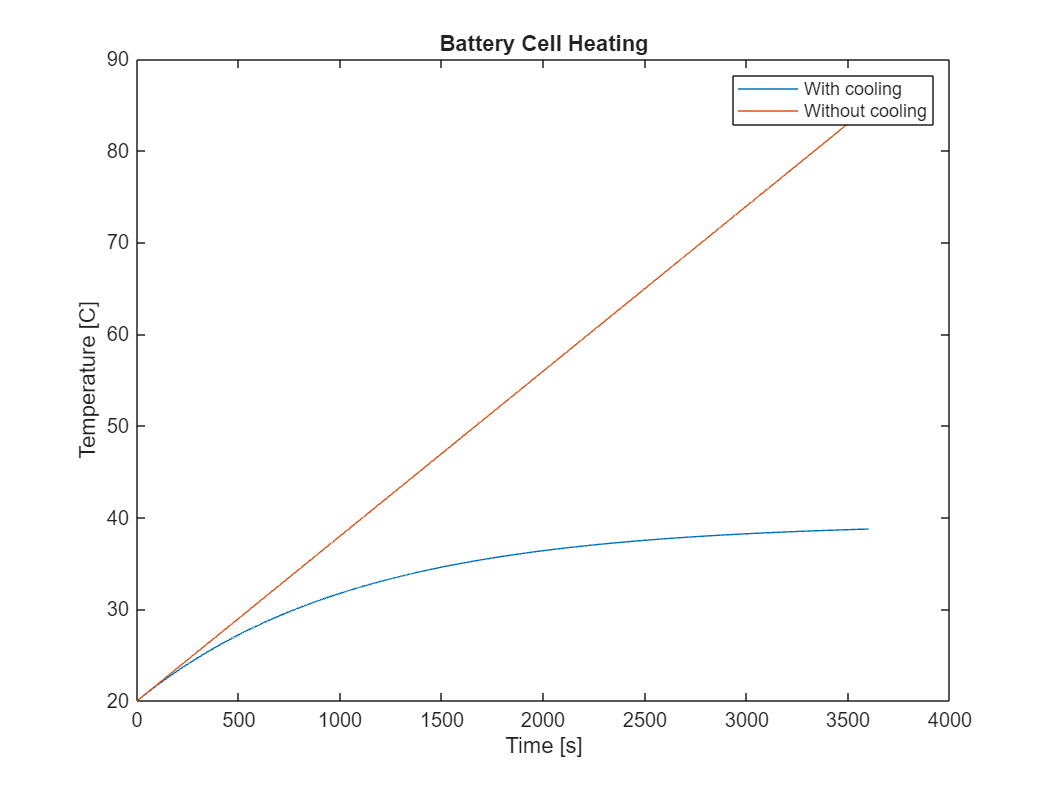


function CheckJouleHeating(Answer)
switch Answer
    case "0"
        warning("Please select an answer.")
    case "1"
        warning("This is not a correct way to compute Joule heating, please try again.")
    case "2"
        disp("Good job! You selected the right answer.")
    case "3"
        warning("This is not a correct way to compute Joule heating, please try again.")
    case "4"
        warning("This is not a correct way to compute Joule heating, please try again.")
end
end

function CheckCoolingSystem(Choice)
switch Choice
    case "None"
        warning("Please select one of the other options.")
    case "NatConv"
        disp("Yes, you could use natural convection with the following formula:")
        syms Q_loss h S T T_ambient
        displayFormula("Q_loss = h*S*(T-T_ambient)")
        disp("with:")
        disp("  - h the natural convection heat transfer coefficient")
        disp("  - S the outer surface of the battery cell")
        disp("  - T the battery temperature")
        disp("  - T ambient the ambient temperature")
        disp("")
        disp("For natural convection you can use:")
        disp("  h = 1 W/(m2*K)")
        disp("  T_ambient = 20 C")
        disp("  S = 0.004 m^2")
    case "ForcedConv"
        disp("Yes, you could use forced convection with the following formula:")
        syms Q_loss h S T T_ambient
        displayFormula("Q_loss = h*S*(T-T_ambient)")
        disp("with:")
        disp("  - h the natural convection heat transfer coefficient")

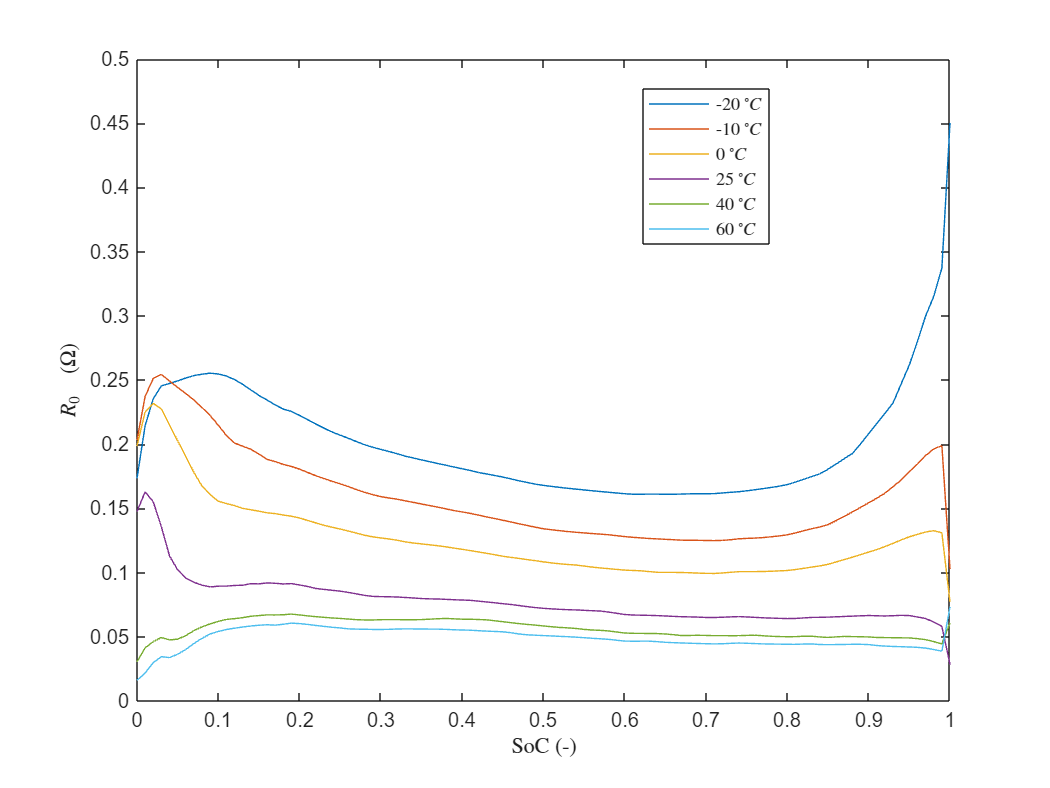

        disp("  - S the outer surface of the battery cell")
        disp("  - T the battery temperature")
        disp("  - T ambient the ambient temperature")
        disp("")
        disp("For natural convection you can use:")
        disp("  h = 20 W/(m2*K)")
        disp("  T_ambient = 20 C")
        disp("  S = 0.004 m^2")
    case "Cooled"
        disp("Yes, you could cool down the battery environment (heat pump):")
        syms Q_loss h S T T_ambient
        displayFormula("Q_loss = h*S*(T-T_ambient)")
        disp("with:")
        disp("  - h the natural convection heat transfer coefficient")
        disp("  - S the outer surface of the battery cell")
        disp("  - T the battery temperature")
        disp("  - T ambient the ambient temperature")
        disp("")

        disp("For natural convection you can use:")
        disp("  h = 1 W/(m2*K)")
        disp("  T_ambient = 0 C")
        disp("  S = 0.004 m^2")
    case "HeatSink"
        disp("Yes, you could cool down the battery environment (heat pump):")
        syms Q_loss h S T T_ambient Eff
        displayFormula("Q_loss = h*S*Eff*(T-T_ambient)")
        disp("with:")
        disp("  - h the natural convection heat transfer coefficient")
        disp("  - S surface heat fins")
        disp("  - Eff is the efficacity of the heat fins")
        disp("  - T the battery temperature")
        disp("  - T ambient the ambient temperature")
        disp("")
        disp("For natural convection you can use:")
        disp("  h = 1 W/(m2*K)")
        disp("  S = 0.01 m2")
        disp("  T_ambient = 0 C")
        disp("  Eff = 70 %")
end
end

function CheckComputeHeatLoss(Choice,fun)
    T = 35;
    switch Choice
        case "NatConv"
            Choice = "natural convection";
            h = 1;
            Surface = 0.004;
            Tamb = 20;
            Eff = 1;
        case "ForcedConv"
            Choice = "forced convection";
            h = 20;
            Surface = 0.004;
            Tamb = 20;
            Eff = 1;
        case "Cooled"
            Choice = "natural convection in cooled environment";
            h = 1;
            Surface = 0.004;
            Tamb = 0;
            Eff = 1;
        case "HeatSink"
            Choice = "heat sink in cooled environment";
            h = 1;
            Surface = 0.01;
            Tamb = 0;
            Eff = 0.7;
    end

    HL = fun(T);
    HLSoln = h*Surface*Eff*(T-Tamb);
    if HL == HLSoln
        disp("Good job! You implemented ComputeHeatLoss correcly.")
    else
        warning("Your implementation of ComputeHeatLoss is not consistant with your choice of "+...
            Choice+" cooling.")
    end

end

function CheckUpdateWithoutCooling(fun)
    T = 20;
    ts = 1;
    M = 5;
    R0 = 0.3;
    i = 2;

    Soln = T + ts/M*R0*i^2;
    Result = fun(T,ts,M,R0,i);

    if Soln == Result
        disp("Good job! You defined the temperature update correctly.")
    else
        warning("Your implementation of the temperature update is incorrect. Please try again.")
    end
    
end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))